## Ejemplo de implementación

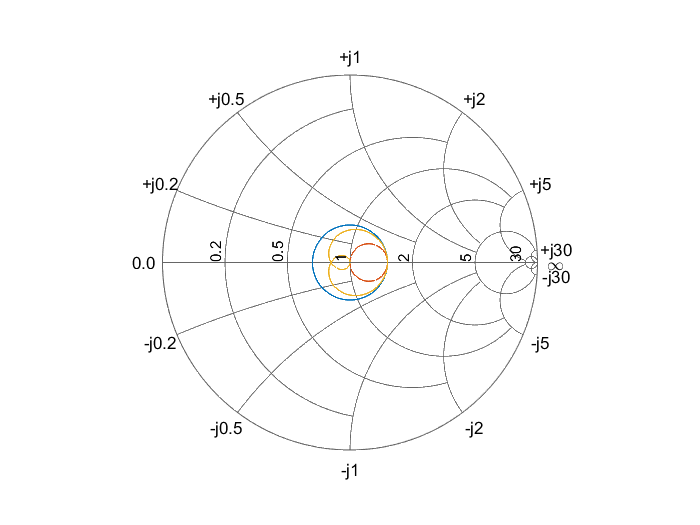

f = 60e6;
Z0 = 50;
ZL = 75;
Z1 = sqrt(Z0*ZL);
f_f0  = 0:1e-3:4;
theta = pi/2*f_f0;

% Impedancia Zin sin adaptar
Zin_0 = Z0*(ZL+1i*Z0*tan(theta)) ./ (Z0+1i*ZL*tan(theta)); GZin_0 = z2gamma(Zin_0);
Zin_1 = Z1*(ZL+1i*Z1*tan(theta)) ./ (Z1+1i*ZL*tan(theta)); GZin_1 = z2gamma(Zin_1); 
Zin_2 = Z0*(Zin_1+1i*Z0*tan(theta)) ./ (Z0+1i*Zin_1.*tan(theta)); GZin_2 = z2gamma(Zin_2); 

figure; % Create a new 
smithplot(GZin_0);
hold on
smithplot(GZin_1);
smithplot(GZin_2);

## Ejercicio 1

a) Los parámetros conocidos son:

Z0 = 50; ZL = 300;

Desarrollo:

Z1 = sqrt(Z0*ZL)

Z1 = 122.4745

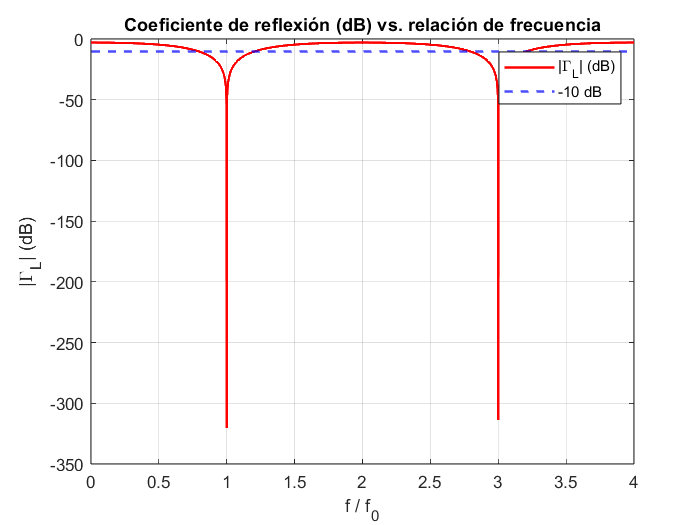

f_f0  = 0:1e-3:4;
theta = pi/2*f_f0;

% Impedancia de entrada sin adaptar 
Zin_0 = Z0*(ZL+1i*Z0*tan(theta)) ./ (Z0+1i*ZL*tan(theta)); GZin_0 = z2gamma(Zin_0);
% Impedancia de entrada al transformador
Zin_1 = Z1*(ZL+1i*Z1*tan(theta)) ./ (Z1+1i*ZL*tan(theta)); GZin_1 = z2gamma(Zin_1); 
% Impedancia de entrada adaptada
Zin_2 = Z0*(Zin_1+1i*Z0*tan(theta)) ./ (Z0+1i*Zin_1.*tan(theta)); GZin_2 = z2gamma(Zin_2); 

% Conversión a dB
GZin_2_dB = 20 * log10(abs(GZin_2));

% Plot
figure;
plot(f_f0, GZin_2_dB, 'r', 'LineWidth', 1.5);
hold on;
yline(-10, 'b--', 'LineWidth', 1.5); % Línea horizontal
xlabel('f / f_0');
ylabel('|\Gamma_L| (dB)');
title('Coeficiente de reflexión (dB) vs. relación de frecuencia');
grid on;
legend('|\Gamma_L| (dB)', '-10 dB ');
hold off;

Por inspección visual, el BW se encuentra entre $0.7882 < f/f_0 < 1.212 $